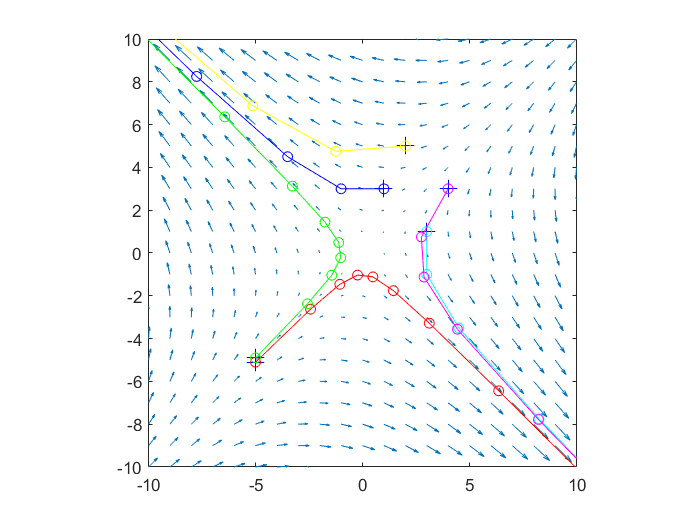

clear;
close all;
clc;

A = 1/4*[5 -3; -3 5];
x = -10:1:10;
y = x;
[X,Y] = meshgrid(x,y);
Z = A*[X(:)'; Y(:)'];
u = Z(1,:);
v = Z(2,:);
fig = figure();
quiver(X(:)',Y(:)',u-X(:)',v-Y(:)')
axis([-10 10 -10 10]);
daspect([1 1 1]);
hold on;


x = [  -5   -5   1 3 2 4];
y = [-5.1 -4.9   3 1 5 3];

plot(x,y,"b+",'MarkerSize',10);

[M, N] = size(x);

for i = 1:N
    p(:,:,i) = [x(i);y(i)];
end

colors =["red","green","blue","cyan","yellow","magenta"];

for i=2:10
    for j=1:N
        R(:,:,j) = A*p(:,i-1,j);
    end  
    p = cat(2,p,R);
    for k=1:N   
        plot(p(1,i-1:i,k),p(2,i-1:i,k),'Color',colors(k),...
            'Marker','o');
    end
    drawnow;
    pause(.5);
end